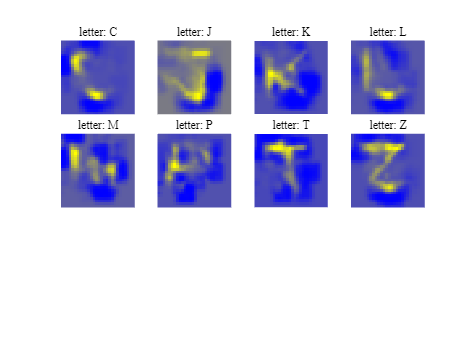

clc;
clear;
close all;
set(groot,'defaultAxesFontSize',12);
N = 28;
M = 28;
Z = 1;
patch_h = 7;
patch_w = 7;
Bx = N - patch_w;
By = M - patch_h;
F = patch_h * patch_w * Z;
K = Bx + By;
expected_len = 2 * (F + K);
clauseFile = 'emnist_clause.txt';
fid = fopen(clauseFile,'r');
if fid == -1
    error('Could not open clauses file');
end
rawClauses = textscan(fid,'%s');
fclose(fid);
clauses = rawClauses{1};
numClauses = length(clauses);

weights10 = [98, -26, 23, -256, -256, -17, 6, 59, -12, -4, -22, 80, 7, 61, -256, 65, -256, -14, -2, 88, 61, -60, 101, -253, 47, 6, 136, 58, -24, 106, 1, -20, 103, -256, -7, -7, 16, -18, 60, 107, 88, 65, -28, 10, 104, 108, -25, -38, -35, 11, -256, -14, -6, -28, -1, 29, -18, -256, -10, -254, 41, 31, -42, -4, 80, -7, -14, -12, -256, 158, -256, 78, -14, -25, -20, -11, -256, 7, 132, 1, -17, -256, 36, -13, -6, 102, -256, -256, -10, -4, -29, 80, -11, 146, 102, 8, -256, -256, -25, -256, -256, 151, 19, 47, -23, 168, -8, 29, -256, -256, -32, -253, -256, 23, 0, -10, 66, -23, 89, 5, -256, -41, 125, 19, 124, 70, 120, 5, 19, -5, -256, -256, -256, 66, 92, -2, 154, 160, 61, -251,6,-156,2,20,160,-1,9,-120,23,0,-1,-10];
weights11 = [-20, 2, -41, -11, -256, 6, 79, -256, 131, -12, -54, -256, -256, -35, 102, -256, -16, -256, -253, 79, -28, -62, -256, -256, -256, -256, -256, -256, -14, -40, -70, 101, -43, 170, -256, -256, -256, -256, -28, -56, -46, -256, -34, -17, -49, -34, -43, -36, -31, -256, 89, 13, 1, -256, -12, 115, -20, 106, 116, -256, 1, -10, 61, -30, -2, -256, -256, 161, 72, -256, 72, -13, -14, -16, 82, -14, 107, 167, -256, -256, -256, 54, -35, -256, 88, -64, -256, -256, 80, -256, 101, -256, -11, -256, -256, -256, 20, 94, 46, 1, 16, -256, -256, -256, -18, -256, 32, -256, -256, -256, 24, -256, 145, -25, -1, -256, -10, -256, -61, -256, -14, 97, -256, -256, -5, -256, -256, -256, -12, -11, 67, 76, 164, -256, -256, 134, -256, -256, -251, -252,12,-9,2,-24,-100,-1,-24,-67,10,14,-24,10];
weights12 = [-3, -50, -62, 8, -24, 156, 77, 178, -7, 72, 12, 126, 89, -34, 17, 13, -25, -37, 113, -10, 42, -39, 52, -7, 3, -7, 15, 77, -2, 39, -20, -22, 0, 20, 72, 3, 96, 89, 66, 66, 12, 50, 72, 113, 71, 91, 54, -32, 30, 18, -27, -256, -35, -57, 3, -15, 104, -27, 29, -256, -15, 113, -35, 29, 138, 44, -25, 13, -20, -27, -10, 106, 101, -29, -35, 148, -24, -17, 2, 74, 101, -39, 5, 123, 8, 69, -8, -17, -20, 82, -40, -7, 57, 13, -2, 143, -47, -256, -39, -7, 15, 37, 113, 74, -10, -7, -5, -12, -256, -13, 86, -3, -7, -3, -8, 106, 12, 49, 92, 161, -20, -52, 8, 81, 8, -47, 108, 86, 155, -5, -8, 3, -256, 108, 121, 8, 104, 92, 150, 166,0,0,0,0,0,0,0,0,0,0,0,0];
weights13 = [-7, 8, -30, 86, 53, -1, 40, 0, -19, 143, 121, 104, -29, 55, 28, -7, 65, 16, -8, -256, 1, 104, 52, 10, 7, 10, -12, 4, -37, 22, 26, -22, 138, -252, 88, -14, 60, 88, -4, 66, 22, 70, 103, 67, 68, 84, 107, 89, 149, 48, -22, 13, 84, 12, -5, 42, 162, -32, -19, 4, -23, 80, -12, 168, 41, 19, 67, 22, 14, -256, 58, 10, 86, 24, -22, -18, -5, -256, -11, -4, 116, -25, 48, 106, -14, 82, -256, 26, -256, -12, -22, -8, 182, -10, -17, 112, -16, -17, 2, -8, 11, -6, 91, 78, 12, -28, 19, -256, -253, 28, -28, -254, -26, 94, 31, 11, -256, 41, 82, 7, 130, -41, -24, 2, 6, -40, 20, 112, 101, -1, 10, -7, -256, -2, 104, 10, 12, 17, 13, -253,0,0,0,0,0,0,0,0,0,0,0,0];
weights14 = [-2, 40, 44, 1, 49, 8, -8, 29, 24, 6, -46, -22, 24, -6, 4, -256, -18, 82, -12, -10, 55, 52, -4, 102, -12, 17, 38, -256, 47, -256, -66, 23, -256, 7, -31, 37, -19, 0, -20, -60, -256, -52, 53, -256, -56, -35, 86, 96, 12, -13, 66, 67, -16, 103, 95, 4, -256, 40, -13, -256, 162, -256, 88, -24, -17, -256, 68, -5, 18, 42, -2, 54, -4, 134, 80, -6, 11, 43, 25, -1, -256, 116, -16, -256, 4, -71, -2, 120, 168, 65, 76, 23, -8, 14, 19, -256, 108, 60, 103, -4, 4, 28, -256, -256, 119, 40, -11, 41, -254, 53, 104, 115, 24, 38, -256, 74, -7, 12, -61, -18, -14, 71, 14, 7, -256, -6, 7, 29, -256, -256, 2, 13, 23, 41, -22, 19, 0, -8, -254, 30,0,0,0,0,0,100,0,0,0,0,0,0];
weights15 = [191, -4, 188, 72, 244, 31, -29, -17, -17, -40, -128, 127, -116, 242, 0, 129, 56, 139, -18, 0, 56, -120, 187, -32, 44, 127, -24, 35, -136, 92, -221, -52, -78, 0, 120, 144, -224, -189, -4, 236, 200, 172, 104, 88, -252, -256, 140, -216, -224, 242, 3, -4, -248, 104, 63, 30, -65, -63, 31, -189, 222, -255, 96, 222, -208, 0, 8, -161, 159, 222, 41, 16, 0, 4, 112, 31, 159, -225, -64, -192, -128, -97, 16, 0, 191, 191, 202, 35, -66, 100, 48, 4, 14, 255, -254, -4, 129, -126, 118, -2, 43, 253, -235, -254, 246, -13, 255, 253, 249, 249, -253, 245, 240, 248, 81, -196, 253, -245, -247, -241, 129, 3, -240, 15, -176, -254, 144, -124, 206, -17, -161, -176, 114, -112, -224, -209, 244, 224, 127, -200,0,0,170,100,0,0,0,0,0,0,0,0];
weights16 = [55, -256, 72, -2, -256, -17, -6, -2, -256, 5, -52, -19, 104, -13, 78, 0, 34, 31, 154, -18, -20, 31, 37, -2, 54, -11, 7, 100, -28, 23, -66, -2, -19, -254, -25, 55, -13, -12, 41, 66, 98, -32, -30, -7, 55, -19, -47, -256, -5, -11, -26, -14, 22, 89, 10, 12, -256, -34, -14, 0, 16, -4, -37, -28, -22, -256, -26, 38, -25, 37, 97, -5, -13, -10, -32, 115, -18, 32, 74, -13, -256, -25, -18, -256, 84, 72, 253, -256, -1, 60, -30, 35, -256, 56, 130, -256, -37, -31, -31, 82, 43, 2, -16, -256, -24, 95, 193, 94, -256, -17, -5, -4, -28, -256, 58, -1, 110, -256, 41, 85, -22, -41, 56, 73, 16, 44, -10, -256, -256, 77, -7, -256, -256, 65, -23, 24, -7, -5, -256, -252,200,0,0,0,0,0,0,0,0,0,0,0];
weights17 = [-12, 115, -49, -11, 43, -10, -8, -16, 54, 22, 85, -22, -31, 24, -7, -16, -1, -8, -256, 65, 32, -50, -8, 14, -256, 68, -13, -7, 85, -256, 116, 59, -47, 2, 4, -16, 7, -7, -256, -256, -55, 26, 53, -11, -256, -256, 30, 38, 10, 4, 79, 74, 0, -256, 7, -26, -16, 86, 37, -251, -6, 31, 116, -20, 5, 133, 1, -6, 6, -19, -256, -12, 13, -6, 62, -7, 16, -5, -256, 5, 55, 60, 124, 103, -1, -256, -256, -6, 4, -28, 76, 7, 6, -28, -256, -11, 119, 92, 47, -256, -256, -13, -20, -14, 22, -31, -256, -18, 202, -256, 20, -252, 20, 68, -256, 32, -8, 154, -62, -6, 14, 113, -20, -256, -11, -34, -23, -4, -12, -11, 20, 64, 48, -29, -26, -14, -256, -256, -254, -252,0,150,0,0,0,0,0,0,0,0,0,0];
weights18 = [29, 19, 70, 97, -11, 61, 26, 18, -17, -1, -37, -18, 124, 44, -10, 88, 17, -22, 2, -6, 5, 44, -11, 24, 106, 20, 4, -256, 59, 139, 56, 46, 19, 2, 44, -11, 17, -16, 134, 53, 107, 56, -23, 62, 43, -4, -38, -256, -16, 82, 2, 12, 23, 13, 66, 10, 38, 38, 16, 49, -14, -8, -37, -26, 2, 4, -8, -1, 72, -8, 4, -256, -2, -20, -16, 23, 73, -20, -256, 17, -24, -16, -18, -17, 5, 66, -6, -256, -14, 80, -22, 22, 2, 2, -6, 18, -41, 24, -4, -2, 7, -6, 55, 40, -5, -19, -11, -8, -254, 7, -19, 4, 49, -30, 14, 7, 43, -7, 53, -18, -19, -7, 6, 60, 53, 80, -6, -256, 19, 13, 71, -14, 12, 12, -19, 7, -18, -7, 2, -252,0,0,0,0,0,0,0,0,0,0,0,0];
weights19 = [-5, 100, 94, 19, 42, 12, 2, -256, 30, -28, 62, -20, -29, 10, -11, 34, -17, 109, -256, 18, 22, 49, -16, 54, 1, 44, 30, -256, 112, -40, 114, 24, -41, 0, 54, 96, -20, 1, -31, -61, -48, 25, -20, -17, -50, -32, 26, 50, -18, -7, 48, 43, 13, 96, 5, -16, 11, 42, 19, -256, 5, 19, 86, -29, 8, 46, 67, -256, 73, 19, -256, -1, 40, 96, 77, -12, 22, -12, 0, -16, -256, 97, -4, -14, 6, -70, -253, 78, -24, -12, 77, 38, -1, 16, 10, -256, 116, 56, 74, -18, -2, 13, -20, -13, 110, 6, -256, 58, 35, 120, 61, 72, 54, -5, -17, -7, -254, -6, -67, -19, -13, 85, 43, 17, -8, 52, -6, -1, -5, -13, 22, 82, 13, -31, -26, -11, 0, -8, -251, 29,0,0,0,0,150,0,0,0,0,0,0,0];

weights0 = [17, 15, 0, 47, -256, 39, 173, 97, 3, 25, -256, 121, 2, -256, -129, 34, -72, 54, -8, -35, -8, 30, 74, 37, -7, 143, 57, -67, 111, 126, -256, 15, 39, 114, 15, 8, 49, 8, 59, 17, -30, 113, -82, -256, -37, 13, -91, 60, -256, -2, -44, -27, 163, -256, 37, -256, 96, 123, -256, 25, -5, 59, -256, 161, 18, 165, -30, 27, 208, 5, 131, -5, 166, -13, 113, -76, -5, -84, -256, -50, 247, 230, 15, -12, 92, 69, -256, -24, -34, -27, 178, -256, -256, 163, -256, 64, -82, 3, 188, 8, 97, -2, 77, 22, 42, -2, 8, -256, 59, -24, 2, 15, -71, -25, -18, -256, 24, 108, 134, -256, -18, -256, 66, 151, -13, 0, -123, 143, -50, 126, -256, -24, -256, 45, 109, 5, -3, -45, 15, 66,0,0,0,0,0,0,0,0,0,0,0,0];
weights1 = [42, 77, 28, -20, -256, 105, -17, -4, 28, 56, -256, -17, 109, -15, 46, 55, 69, -256, 48, 115, 106, 10, -1, 71, 80, 60, 53, -36, -13, -34, -11, -1, -4, -7, -21, 36, 76, 127, -14, -24, 77, -27, 130, -256, 0, -256, 113, -1, -4, 67, 153, 106, -53, 21, 55, 108, 4, -17, 1, 88, 45, 99, -18, -81, -17, -29, 45, -4, -28, 64, -53, 3, 27, 57, -22, 161, 11, 118, 143, 136, -38, -31, -256, -15, -31, -22, 24, 108, -22, 94, -21, 164, -256, -29, 95, -256, 118, 31, -45, 238, -25, 21, 3, -31, 154, 141, 87, -256, 3, 105, 31, 39, 120, 46, -256, 125, -6, -3, 22, -256, -22, 113, -6, -43, -11, 109, 43, -25, 92, -17, -256, -7, 109, -24, -15, 154, 13, 133, -20, 42,0,0,0,0,0,0,0,0,0,0,0,0];
weights2 = [-32, -8, 31, 43, 59, -18, 10, 99, 0, 22, 67, 78, -21, 95, 53, 18, 41, 88, 31, 46, 1, -35, -8, -34, -24, 15, -22, 111, -256, 85, 64, -29, -28, -256, 60, 27, -17, -14, 84, 14, 24, -52, 50, 67, 90, 22, 104, -31, -256, 10, 78, 48, -55, 7, -43, 11, 48, 104, -256, 7, 8, -21, 64, -46, 181, 34, -3, -256, 53, 74, -95, -8, 20, -11, -17, 88, -15, 21, 38, 63, -256, -256, -7, 21, 24, 141, -14, -3, 53, 35, -29, -256, 31, 43, 109, 115, 31, 4, -49, -256, 144, 48, 59, -22, -8, -31, -8, 22, -22, -7, 22, 21, 52, 42, 11, 11, -4, 10, 48, 94, 10, -256, -256, -39, -3, -18, 25, -1, 141, 46, -15, -17, 17, 85, 18, -36, 20, 67, 199, -21,255,255,0,0,0,0,0,0,0,0,0,255];
weights3 = [108, 71, -18, 32, 14, 22, -22, 0, 1, -22, 31, -21, 45, 112, 112, 8, -49, 108, -27, -13, 27, 99, 45, 52, 7, -59, -14, -55, 137, -41, 186, 48, 71, 41, 113, 122, 36, 45, 24, 11, -24, 164, -20, 63, -256, -4, -55, 88, 3, -18, -10, 38, 174, 130, 101, -25, 4, -4, 139, -20, -256, 41, 178, 136, 15, -29, 62, 109, 27, -14, 102, 195, -1, 115, 45, -32, 73, -36, -42, 17, 165, 97, 20, 111, 35, 20, 112, -31, -27, 94, 146, -256, 77, -31, -6, 1, -35, 3, 158, -256, 14, 63, -6, 50, 0, 71, -29, -256, 125, -25, 104, 78, -32, -256, 46, -22, 0, -41, 41, 130, 143, 148, 74, 141, 22, 48, 55, 70, -48, 17, 171, 6, 83, 41, -20, 63, -256, -13, 10, 31,0,0,255,255,0,0,0,0,0,255,255,0];
weights4 = [104, 29, -6, -256, -256, 46, -52, -18, 14, -256, -7, -14, 24, -256, -43, 52, 4, -14, -31, 87, 14, 29, 4, 46, 3, -62, 48, -256, -35, -38, -7, 13, 39, -6, -20, 66, 27, 22, -17, 42, 57, 27, 112, -7, -256, 14, 106, 22, -256, -256, 22, 34, 13, 0, 74, 90, -27, -21, -256, -63, -24, 41, -14, -63, -256, -48, 62, -256, -25, 50, -90, 63, -256, -11, -17, 80, 105, 115, 84, 74, -29, -34, 1, -13, -256, -15, -6, -256, -29, 29, 21, 92, 46, -36, 8, -256, 120, 115, -71, -256, -21, -31, -10, -31, 18, 17, -29, -256, -13, -21, -3, 88, 108, -256, 7, 85, -256, -31, -24, -6, 0, 130, -13, -7, -256, 29, 104, -21, 74, -256, -256, 164, -256, -256, -18, 17, -256, 24, -17, 50,0,0,0,0,0,0,0,0,255,255,0,0];
weights5 = [-11, 28, 18, -13, 74, -4, 0, -18, -3, -27, 63, -7, 73, -256, -105, -36, -256, 8, -24, -80, 3, 49, 28, 24, 3, 77, -20, 3, 7, 140, -256, -21, 18, 31, -13, -256, -17, 49, -14, -4, -31, 31, -70, 52, -7, 42, -84, -7, 35, -7, -29, -27, 155, -11, 15, -256, 157, -11, 14, -3, -25, -1, -256, 25, -256, 90, -256, -3, 70, -29, 84, -28, 8, 3, 113, -56, 99, -73, -50, -46, 39, 109, 155, 56, 3, 8, -15, -14, 31, -28, 34, 0, 122, 105, 13, -256, -76, -15, 84, -256, -28, 74, -14, 10, 8, 104, -27, -256, 38, 56, -25, 78, -81, -11, 155, -256, 41, 91, -17, -14, -256, -38, 22, 167, 168, 133, -85, 24, -67, -3, -256, 144, 4, -7, 71, 74, -8, -36, -4, -6,0,0,0,0,0,0,0,0,0,0,0,0];
weights6 = [-256, 17, 11, -256, 41, 8, 35, -256, -11, 0, 31, -15, -10, -256, 20, -256, -27, -15, -1, -87, 34, 111, 0, 28, -1, 74, 17, -34, 154, -25, -256, -7, 88, 8, -256, -28, -17, -10, -15, 41, -22, -3, -71, -13, -21, 10, -80, 6, 1, -4, -256, -256, -55, -7, 39, -256, -36, -21, 1, -14, -3, 7, -256, 137, -21, -31, -22, -8, -35, -32, 98, -256, 97, -10, 14, -256, -17, -74, -256, -256, -34, -21, -4, -22, -25, -20, 15, -7, -25, -256, -28, -256, -11, -39, -4, -7, -80, -18, -50, -256, -7, -25, -256, 143, 1, -10, 1, 17, 45, 4, -256, -98, -256, 69, -3, -256, 27, 14, 1, -11, -256, -256, 4, -45, 11, -17, 109, 56, -59, -256, -256, -29, -256, -256, -17, -13, -15, -24, -15, 31,0,0,0,0,0,0,150,90,0,0,0,0];
weights7 = [-27, 3, 81, 150, 22, 0, 140, 134, 57, 85, 11, 111, -1, 92, 66, 167, 102, 18, 92, 130, 56, -67, 67, 11, 83, -4, 80, -24, -38, 76, 69, 77, -256, 80, 136, 6, 34, 11, 84, 43, 109, -6, 126, 14, -21, 13, 127, 36, 192, 91, 87, 66, -46, 73, -7, 130, 27, 69, 71, 140, 115, 3, 78, -81, 64, 160, -25, 113, 55, 90, 90, 11, 36, 109, -256, 134, -17, 144, 133, 95, -256, -256, -7, 132, 175, 34, -14, 122, -7, 49, -256, -256, -256, 143, 10, 46, 136, -20, 147, -256, 36, 102, 140, -256, 17, 0, 101, 195, -17, 41, 146, -55, 150, 25, -256, 118, 140, 81, 59, 20, 155, -15, 104, -28, 25, -13, -62, 48, 99, 133, 171, -256, 42, 118, 139, 6, 20, 97, 22, 42,0,0,0,0,0,0,0,0,0,0,0,0];
weights8 = [-34, -18, 17, 14, 18, -6, -57, -21, 52, 48, 41, 7, -25, -4, 88, -43, 87, 4, 70, -85, -15, 48, -6, -20, 31, -38, -31, 175, -256, -32, -6, 34, 56, -13, -21, 7, 7, -24, 31, 77, -8, -256, -70, 83, 164, 111, -92, -18, -256, 53, -24, -256, -55, -3, -32, -46, -31, 14, -256, 36, 53, -13, -15, 98, 28, -46, 120, -8, -35, -21, -53, -22, -45, -22, 45, -66, -256, -64, -256, -50, -17, 11, 21, -21, -7, 27, -14, 71, 144, -256, -21, -6, -4, -35, -256, 64, -69, 106, -71, -256, 11, -18, -1, 137, -4, -256, 67, -1, -256, 41, -45, 46, -77, 43, 29, -38, -4, -22, -256, 43, -10, -256, -20, -46, 8, -41, 111, -36, -57, -15, -11, -21, -256, 7, -34, -36, 122, -17, 38, -14,255,255,0,0,0,255,0,0,0,0,0,0];
weights9 = [60, -17, 42, -256, -8, 17, 13, -34, 38, 48, -256, -256, -17, -256, 66, 4, 99, -256, 49, 108, -17, -67, 10, -18, 34, 10, 39, 174, -21, -256, -256, 64, -38, 1, -256, -13, 14, -15, -256, -14, 35, 24, 83, -18, 112, -8, 137, 46, -256, 29, -14, 25, -14, -256, -34, 87, -256, -256, -256, 4, 53, -22, -14, -78, -256, -52, 25, -256, -43, 10, 6, 34, -35, -22, -256, 10, -6, 116, 46, 13, -256, -256, 15, -256, -256, -27, 116, 17, 109, -10, -18, -256, -11, -45, -256, -256, 123, -11, -57, -256, -17, -29, -256, -256, -6, -39, 27, 1, 6, 15, 27, -43, 95, 74, 8, 48, 1, 24, -20, -256, -15, 24, -8, -36, 31, -28, -11, -20, 46, -256, -256, -3, -256, -256, -24, -35, 71, -10, -256, -4,221,203,194,190,255,0,0,0,0,0,0,0];

all_weights = {
weights1,...
weights2,...
weights3,...
weights4,...
weights5,...
weights6,...
weights8,...
weights9
};
% FIGURE
% ------------------------------------------------------------
figure;
set(gcf,'Color','white');
labels = {'C','J','K','L','M','P','T','Z'};

for digit = 0:7

    weights = all_weights{digit+1};

    weights = weights(:);

    if length(weights) ~= numClauses
        error(['Mismatch for digit ' num2str(digit)]);
    end

    Global_Map = zeros(N,M);

    % --------------------------------------------------------
    % PROCESS CLAUSES
    % --------------------------------------------------------
    for c = 1:numClauses

        clauseW = weights(c);

        % Use only positive weights
        if clauseW <= 0
            continue;
        end

        clause = clauses{c};

        bits = clause - '0';

        % Remove prefix bits if needed
        bits = bits(75:end);

        if length(bits) ~= expected_len
            continue;
        end

        idx = length(bits);

        % ----------------------------------------------------
        % K+
        % ----------------------------------------------------
        K_pos_raw = bits(idx-K+1 : idx);
        K_pos_raw = K_pos_raw(end:-1:1);

        idx = idx - K;

        % ----------------------------------------------------
        % L+
        % ----------------------------------------------------
        L_pos = bits(idx-F+1 : idx);
        L_pos = L_pos(end:-1:1);

        idx = idx - F;

        % ----------------------------------------------------
        % K-
        % ----------------------------------------------------
        K_neg_raw = bits(idx-K+1 : idx);
        K_neg_raw = K_neg_raw(end:-1:1);

        idx = idx - K;

        % ----------------------------------------------------
        % L-
        % ----------------------------------------------------
        L_neg = bits(idx-F+1 : idx);
        L_neg = L_neg(end:-1:1);

        % ----------------------------------------------------
        % RESHAPE PATCHES
        % ----------------------------------------------------
        L_pos_patch = reshape(L_pos,[patch_h,patch_w]);

        L_neg_patch = reshape(L_neg,[patch_h,patch_w]);

        % ----------------------------------------------------
        % DECODE K+
        % ----------------------------------------------------
        y_bits_pos = K_pos_raw(1:By);
        x_bits_pos = K_pos_raw(By+1:end);

        x_idx_pos = find(x_bits_pos,1,'last');
        y_idx_pos = find(y_bits_pos,1,'last');

        if isempty(x_idx_pos)
            x_range_pos = 1:(Bx+1);
        else
            x_range_pos = x_idx_pos+1:(Bx+1);
        end

        if isempty(y_idx_pos)
            y_range_pos = 1:(By+1);
        else
            y_range_pos = y_idx_pos+1:(By+1);
        end

        % ----------------------------------------------------
        % DECODE K-
        % ----------------------------------------------------
        y_bits_neg = K_neg_raw(1:By);
        x_bits_neg = K_neg_raw(By+1:end);

        x_idx_neg = find(x_bits_neg,1,'first');
        y_idx_neg = find(y_bits_neg,1,'first');

        if isempty(x_idx_neg)
            x_range_neg = 1:(Bx+1);
        else
            x_range_neg = x_idx_neg+1;
        end

        if isempty(y_idx_neg)
            y_range_neg = 1:(By+1);
        else
            y_range_neg = y_idx_neg+1;
        end

        % ----------------------------------------------------
        % REGION
        % ----------------------------------------------------
        x_min = min(x_range_pos);
        x_max = max(x_range_neg);

        y_min = min(y_range_pos);
        y_max = max(y_range_neg);

        x_min = max(1,x_min);
        y_min = max(1,y_min);

        x_max = min(Bx+1,x_max);
        y_max = min(By+1,y_max);

        % ----------------------------------------------------
        % CLAUSE MAP
        % ----------------------------------------------------
        Clause_Map = zeros(N,M);

        row_start = x_min;
        col_start = y_min;

        row_end = row_start + patch_h - 1;
        col_end = col_start + patch_w - 1;

        if row_end > N || col_end > M
            continue;
        end

        % ----------------------------------------------------
        % POSITIVE CONTRIBUTION
        % ----------------------------------------------------
        Clause_Map(row_start:row_end,...
                   col_start:col_end) = ...
        Clause_Map(row_start:row_end,...
                   col_start:col_end) + ...
        clauseW * L_pos_patch;

        % ----------------------------------------------------
        % NEGATIVE CONTRIBUTION
        % ----------------------------------------------------
        Clause_Map(row_start:row_end,...
                   col_start:col_end) = ...
        Clause_Map(row_start:row_end,...
                   col_start:col_end) - ...
        clauseW * L_neg_patch;

        % ----------------------------------------------------
        % AGGREGATE
        % ----------------------------------------------------
        Global_Map = Global_Map + Clause_Map;

    end
% ========================================================
% MULTIPLE BLUR VISUALIZATION
% Creates 10 figures with different blur strengths
% ========================================================

blur_values = [0.8];

for b = 1:length(blur_values)

    sigma = blur_values(b);

    % ====================================================
    % COPY ORIGINAL MAP
    % ====================================================
    tempMap = Global_Map;

    % ----------------------------------------------------
    % NORMALIZE
    % ----------------------------------------------------
    tempMap = tempMap - min(tempMap(:));

    if max(tempMap(:)) ~= 0
        tempMap = tempMap ./ max(tempMap(:));
    end

    % ----------------------------------------------------
    % FLIP + ROTATE
    % ----------------------------------------------------
    tempMap = flipud(tempMap);

    tempMap = rot90(tempMap,3);

    % ----------------------------------------------------
    % SOFT THRESHOLD
    % ----------------------------------------------------
    threshold = 0.4;

    weak_mask = tempMap < threshold;

    tempMap(weak_mask) = ...
        tempMap(weak_mask) .* ...
        (tempMap(weak_mask) / threshold).^2;

    % ----------------------------------------------------
    % APPLY DIFFERENT BLUR
    % ----------------------------------------------------
    if sigma > 0
        tempMap = imgaussfilt(tempMap,sigma);
    end

    % ----------------------------------------------------
    % RE-NORMALIZE
    % ----------------------------------------------------
    tempMap = tempMap - min(tempMap(:));

    if max(tempMap(:)) ~= 0
        tempMap = tempMap ./ max(tempMap(:));
    end

    % ----------------------------------------------------
    % CONTRAST ENHANCEMENT
    % ----------------------------------------------------
    tempMap = tempMap .^ 2;

    % ====================================================
    % FIGURE 2 : BLUE-YELLOW HEATMAP
    % ====================================================
    figure(200 + b);
    
    subplot(2,4,digit+1);

    imagesc(tempMap);

    blueYellowMap = [
        linspace(0,1,256)', ...
        linspace(0,1,256)', ...
        linspace(1,0,256)'
    ];

    colormap(gca,blueYellowMap);
    caxis([0 1]);

    axis image off;

    title(['letter: ', upper(labels{digit+1})], ...
      'FontSize',12, ...
      'FontWeight','normal', ...
      'FontName','Times New Roman');

% ==========================================
% MANUAL SPACING ADJUSTMENT
% ==========================================
    ax = gca;
    pos = ax.Position;

% Make subplot taller
    pos(4) = pos(4) + 0.05;

% Move bottom row upward
    if digit >= 4
        pos(2) = pos(2) + 0.21;
    end

    ax.Position = pos;
end

% ========================================================
% GLOBAL TITLES
% ========================================================
for b = 1:length(blur_values)
    figure(200 + b);

end

end
exportgraphics(gcf, 'EMNIST_Normalized_Heatmaps.pdf', ...
               'ContentType', 'vector');


% ------------------------------------------------------------
% GLOBAL TITLE
% ------------------------------------------------------------